# Math Review, Discrete-Time Signals, Fourier Analysis of Discrete-Time Signals

## Exercise 1

### **Part 1: Expressing x[n] in Cosine Form**

*Considering the discrete-time signal x, sampled with sampling period Ts: *


$$x[n]=2\sin\left(\omega_0nT_s+\frac{\pi}{6}\right)+\cos\left(\omega_0nT_s\right)$$


*To express it in the form *$x[n]=A\cos\left(\omega_0nT_s+\phi\right)$*, the following identities must be used: *${\gamma}\sin(\alpha+\beta)={\gamma}\sin(\alpha)\cos(\beta)+{\gamma}\cos(\alpha)\sin(\beta)$* and *${\gamma}\cos(\alpha+\beta)={\gamma}\cos(\alpha)\cos(\beta)-{\gamma}\sin(\alpha)\sin(\beta)$*. *

*Using the first identity *${\gamma}\sin(\alpha+\beta)={\gamma}\sin(\alpha)\cos(\beta)+{\gamma}\cos(\alpha)\sin(\beta)$*, the portion of the signal *$2\sin\left(\omega_0nT_s+\frac{\pi}{6}\right)$*can be converted into*

$2\sin\left(\omega_0nT_s+\frac{\pi}{6}\right)=2\sin(\omega_0nT)\cos\left(\frac{\pi}{6}\right)+2\cos(\omega_0nT)\sin\left(\frac{\pi}{6}\right) = \sqrt{3}\sin(\omega_0nT)+\cos(\omega_0nT)$*.*

*Substituting the equivalence back into the original equation for *$x[n]$*: *$x[n]=2\sin\left(\omega_0nT_s+\frac{\pi}{6}\right)+\cos\left(\omega_0nT_s\right) =  \sqrt{3}\sin(\omega_0nT)+\cos(\omega_0nT) + \cos\left(\omega_0nT_s\right) = \sqrt{3}\sin(\omega_0nT)+2\cos(\omega_0nT)$*. *

*Using the second identity *${\gamma}\cos(\alpha+\beta)={\gamma}\cos(\alpha)\cos(\beta)-{\gamma}\sin(\alpha)\sin(\beta)$*, the constants in*$x[n]$* can be assigned to the constants in the identity:*


$$\alpha = \omega_0nT_s \\ -\gamma\sin(\beta)=\sqrt{3} \\\gamma\cos(\beta)=2$$


*Isolating for *$\gamma$*the following equivalences can be obtaind: *$\gamma=-\frac{\sqrt{3}}{\sin(\beta)}$* and *$\gamma=\frac{2}{\cos(\beta)}$

*Setting the *$\gamma$* equal,  *$\beta$* can be solved for:*


$$-\frac{\sqrt{3}}{\sin(\beta)}=\frac{2}{\cos(\beta)} \\\tan(\beta)=-\frac{\sqrt{3}}{2} \\\beta = \tan^{-1}\left(-\frac{\sqrt{3}}{2} \right)$$


*Placing *$\beta$* back into the equation *$\frac{2}{\cos(\beta)}$*:*


$$\gamma=\frac{2}{\cos\left(\tan^{-1}\left(-\frac{\sqrt{3}}{2} \right)\right)}$$


*The values for amplitude *$A$* and phase *$\phi$* can be obtained: *


$$A = \frac{2}{\cos\left(\tan^{-1}\left(-\frac{\sqrt{3}}{2} \right)\right)} =  \sqrt(7) \approx  2.64575\\
\phi =  \tan^{-1}\left(-\frac{\sqrt{3}}{2} \right) \approx -0.71372$$


### **Part 2: Plotting the Signal**

**Assuming that **$\omega_0=5\pi$** rad/s and Fs = 44100 Hz, plotting signal ***x*** within the time interval **$[0, 3]$**.**

Fs = 44100; % Sampling frequency in Hz
Ts = 1/Fs; % Sampling period in seconds (interval between successive samples in a discrete signal)
phi = atan(-sqrt(3)/2);
A = 2/(cos(phi));
w_0 = 5*pi; % rad/s
T = Fs;

n = linspace(0,3,3*T);
x = A*cos(w_0*n+phi);
plot(n, x);
title('Discrete-Time Signal x[n]');
xlabel('Time (seconds)');
ylabel('Amplitude');

**Sources used to complete this section:**

- [https://numpy.org/doc/stable/reference/generated/numpy.linspace.html](https://numpy.org/doc/stable/reference/generated/numpy.linspace.html)

- [https://math.stackexchange.com/questions/645693/finding-amplitude-of-oscillation](https://math.stackexchange.com/questions/645693/finding-amplitude-of-oscillation)

- [https://www.youtube.com/watch?v=lt8R094MyPs&ab_channel=EricCytrynbaum](https://www.youtube.com/watch?v=lt8R094MyPs&ab_channel=EricCytrynbaum)

- https://www.youtube.com/watch?v=sfpvKAXRsnY&ab_channel=EricCytrynbaum

## Exercise 2

**Considering the Euler’s formula, geometric series, and symmetry: **

### **Part 1: Proofs**

**Showing that**

$\sum_{n=0}^{+\infty}\frac{\sin(nx)}{\alpha^n}=\frac{{\alpha}\sin(x)}{1-2{\alpha}\cos(x)+{\alpha}^2}$ with $x \in\mathbb{R}, \alpha \in \mathbb{R}^*$

*Using Euler's identities to convert *$sin$* into its expoential equivalent and simplifying:*


$$\sum_{n=0}^{+\infty}\frac{\sin(nx)}{\alpha^n} = \sum_{n=0}^{+\infty}\frac{e^{jnx}-e^{-jnx}}{2j\alpha^n} =  \sum_{n=0}^{+\infty}\frac{e^{jnx}}{2j\alpha^n} - \sum_{n=0}^{+\infty}\frac{e^{-jnx}}{2j\alpha^n} = \frac{1}{2j}\left[ \sum_{n=0}^{+\infty}\left(\frac{e^{jx}}{\alpha}\right)^n - \sum_{n=0}^{+\infty}\left(\frac{e^{-jx}}{\alpha}\right)^n\right]$$


*Using the geometric series *$\sum_{n=0}^{+\infty}(a)^n = \frac{1}{1-a}$* to replace the summations above:*


$$\frac{1}{2j} \left[ \frac{1}{1 - \frac{e^{jx}}{\alpha}} - \frac{1}{1 - \frac{e^{-jx}}{\alpha}} \right] = 
\frac{1}{2j} \left( \frac{1 - \frac{e^{-jx}}{\alpha} - 1 + \frac{e^{jx}}{\alpha}}{\left(1 - \frac{e^{jx}}{\alpha}\right)\left(1 - \frac{e^{-jx}}{\alpha}\right)} \right) = 
\frac{1}{2j} \left( \frac{\frac{e^{jx}}{\alpha} - \frac{e^{-jx}}{\alpha}}{1 - \frac{e^{jx}}{\alpha} - \frac{e^{-jx}}{\alpha} + \frac{e^{jx - jx}}{\alpha^2}} \right) 






$$


*Using the equivalence *$sin(x) = \frac{e^{jx}-e^{-jx}}{2j}
$* and *$cos(x) = \frac{e^{jx} + e^{-jx}}{2}$* to convert *$\frac{1}{2j} \left( \frac{\frac{e^{jx}}{\alpha} - \frac{e^{-jx}}{\alpha}}{1 - \frac{e^{jx}}{\alpha} - \frac{e^{-jx}}{\alpha} + \frac{e^{jx - jx}}{\alpha^2}} \right) 
$*:*


$$\frac{1}{2j} \left( \frac{\frac{e^{jx}}{\alpha} - \frac{e^{-jx}}{\alpha}}{1 - \frac{e^{jx}}{\alpha} - \frac{e^{-jx}}{\alpha} + \frac{e^{jx - jx}}{\alpha^2}} \right)  =
\frac{1}{2j} \left( \frac{e^{jx} - e^{-jx}}{\alpha} \right) \left( \frac{1}{1 - \frac{e^{jx} + e^{-jx}}{\alpha} + \frac{1}{\alpha^2}} \right)  \\
= \frac{1}{\alpha} sin(x) \left( \frac{1}{1 - \frac{e^{jx} + e^{-jx}}{\alpha} + \frac{1}{\alpha^2}} \right) = 
\frac{1}{\alpha} sin(x) \left( \frac{1}{1 - \frac{2(e^{jx} + e^{-jx})}{2\alpha} + \frac{1}{\alpha^2}} \right) \\
= \frac{\alpha^2}{\alpha^2} \left( \frac{\frac{1}{\alpha}sin(x)}{1 - \frac{2cos(x)}{\alpha} + \frac{1}{\alpha^2}} \right) = 
\left(\frac{\alpha sin(x)}{\alpha^2 - 2\alpha cos(x) + 1} \right) = 
\frac{{\alpha}\sin(x)}{1-2{\alpha}\cos(x)+{\alpha}^2}

$$


### **Part 2: Computing the allowable values for alpha**

*The equation *$\frac{{\alpha}\sin(x)}{1-2{\alpha}\cos(x)+{\alpha}^2}$* is undefined when the denominator is *$0$*. This occurs when *$1-2{\alpha}\cos(x)+{\alpha}^2 = 0$*, which can be solved using the quadratic formula *$x = \frac{-b \pm \sqrt{b^2 - 4ac}}{2a}
$* in terms of *$\alpha$*. Plugging the values *$a=1$*, *$b=-2cos(x)$*, *$c=1$*into the formula, it can be shown that *$\alpha = \frac{--cos(x) \pm \sqrt{(cos(x))^2 - 4(1)(1)}}{2(1)} = 
\frac{2cos(x) \pm 2\sqrt{(cos(x))^2 - 1}}{2} = cos(x) \pm \sqrt{(cos(x))^2 - 1}$

*Observing that the range of *$\cos^2(x)$* is *$[0,1]$*, this leaves the only possible value that will result in a non-negative value under square root to be 1. The value of x that are permitted are therefore *$x_1=0; x_2=\pi$*. Using those values, the square root is zero, leaving only the outside cosine and resulting in *$\alpha_1=1;\alpha_2=-1$*which will lead to an undefined result.*

*The allowable values are* therefore $\alpha \in \mathbb{R} \setminus \{1, -1\}$.

### **Part 3: Odd Function**

*To show mathematically that the function is ***odd***, the equivalence *$f(-x) = -f(x)$ *must be shown. The following identities will be used: *$cos(-x)=cos(x)$* and *$sin(-x) = -sin(x)$*.*


$$f(x) = \frac{\alpha sin(x)}{1 - 2\alpha cos(x) + \alpha^2} \\
f(-x) = \frac{\alpha sin(-x)}{1 - 2\alpha cos(-x) + \alpha^2} = \frac{-\alpha sin(x)}{1 - 2\alpha cos(x) + \alpha^2} = -f(x)$$


**Sources used to complete this section:**

- [**https://amsi.org.au/ESA_Senior_Years/SeniorTopic2/2c/2c_2content_2.html#:~:text=Definitions,in%20the%20domain%20of%20f.**](https://amsi.org.au/ESA_Senior_Years/SeniorTopic2/2c/2c_2content_2.html#:~:text=Definitions,in%20the%20domain%20of%20f.)

- [**https://www.cuemath.com/geometric-series-formula/**](https://www.cuemath.com/geometric-series-formula/)

- [**https://www.purplemath.com/modules/quadform.htm**](https://www.purplemath.com/modules/quadform.htm)

- **https://www.varsitytutors.com/trigonometry-help/quadratic-formula-with-trigonometry**

## Exercise 3

**Considering the signal **$x
$ **represented by the following discrete-time sequence:**


$$x[n] = \begin{cases} 
1 & \text{for } n \in [-N+1, N-1] \\
0 & \text{for } n \notin [-N+1, N-1]
\end{cases}
$$


### **Part 1: Drawing the signal**

**Drawing the signal **$x

$** for **$N = 5$**:**

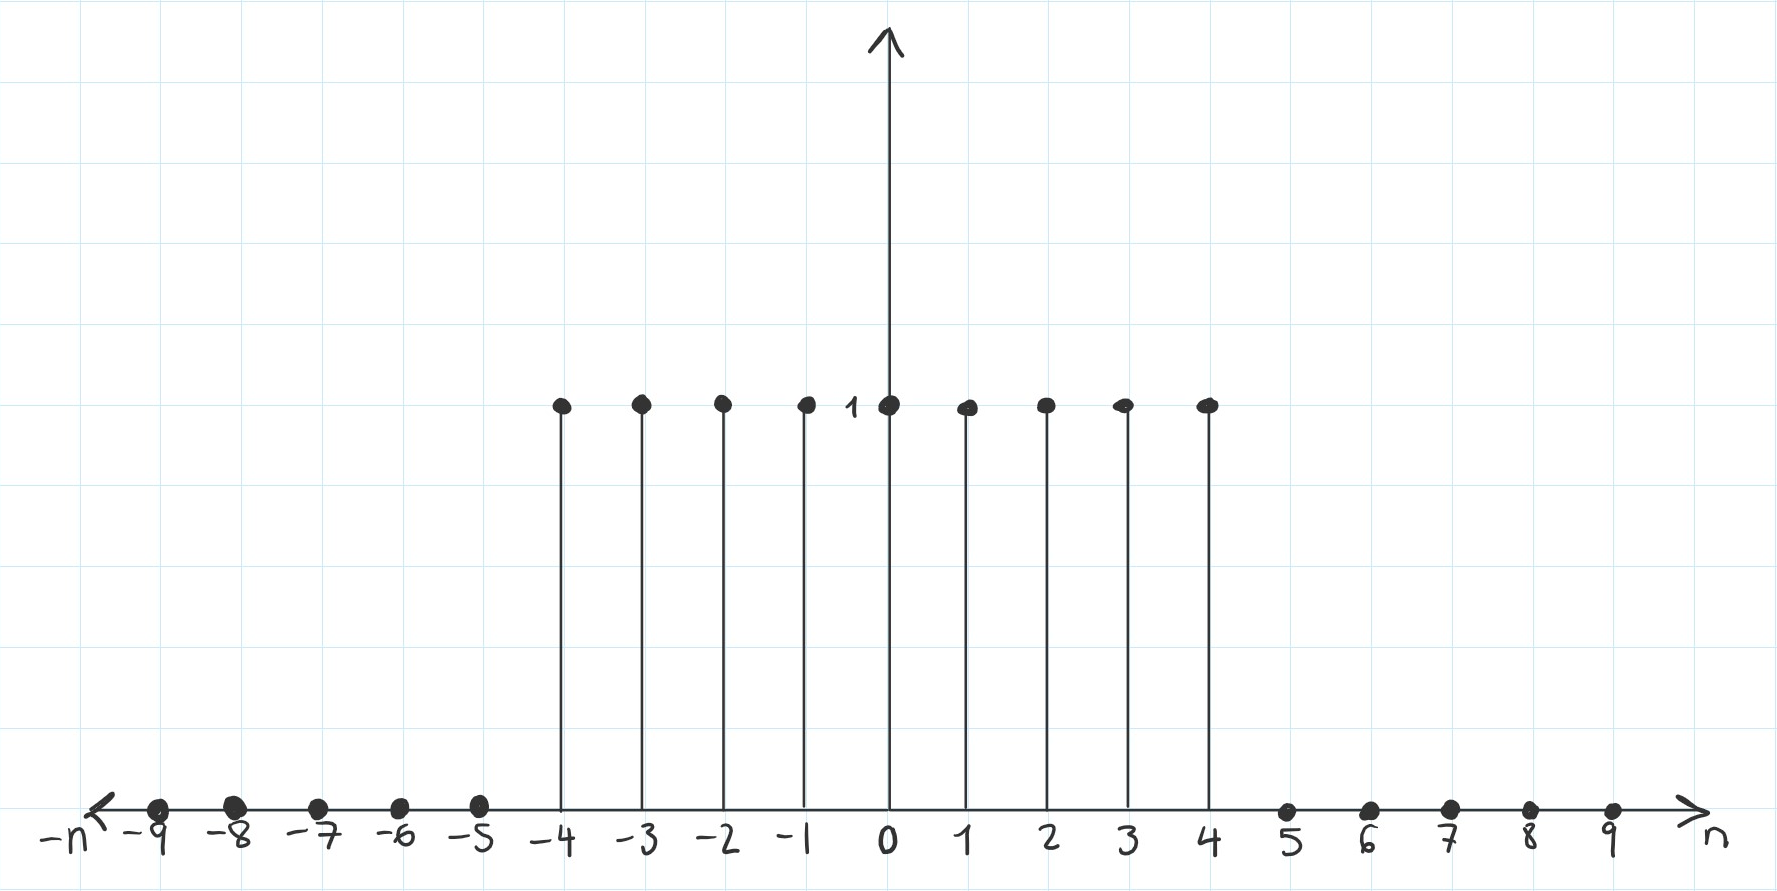

### **Part 2: Discrete-Time Fourier Transform (DTFT) of signal x**

**Computing **$X(\omega)$**, the Discrete-Time Fourier Transform (DTFT) of **$x[n]$**:**

*Using the linearity property, *$x[n]$* can be split up into three different sections. *


$$X(\omega) = \sum_{n=-\infty}^{\infty} x[n] e^{-j\omega n} = \sum_{n=-\infty}^{-5} \left(0\cdot e^{-j\omega n}\right) + \sum_{n=-4}^{4} \left(1\cdot e^{-j\omega n}\right) + \sum_{n=5}^{\infty} \left(0\cdot e^{-j\omega n}\right) = \sum_{n=-4}^{4} \left(1\cdot e^{-j\omega n}\right)
$$


*Using properties of geometric series:*


$$\sum_{n=0}^{N} a^n = \frac{1-a^{N+1}}{1-a} = a \left( \sum_{n=0}^{N-1} a^n \right) = a \left(\frac{1-a^{(N-1)+1}}{1-a}\right)  = a \left( \frac{1-a^{N}}{1-a} \right) 
$$


*The equation can be expanded and converted to two terms containing exponentials. Note that from the original constrants *$(-N+1,N-1)$* will be replaced with *$(-M,M)$* for the purposes of simplying the calculations.*


$$X(\omega) = \sum_{n=-M}^{M} (1\cdot e^{j\omega n}) = \sum_{n=-M}^{M} e^{j\omega n} 
= e^{j\omega M} \sum_{n=0}^{2M} e^{-j\omega n}  = e^{j\omega M} \left(\frac{1 - e^{-j\omega (2M+1)}}{1 - e^{-j\omega}}\right) \\
= e^{j\omega M} \left(\frac{e^{-j{\omega}\frac{2M+1}{2}}e^{j{\omega}\frac{2M+1}{2}} - e^{-j\omega \frac{2M+1}{2}}e^{-j\omega \frac{2M+1}{2}}}{e^{-j\omega \frac{1}{2}}e^{j\omega \frac{1}{2}} - e^{-j\omega\frac{1}{2}}e^{-j\omega\frac{1}{2}}}\right) 
= \left(\frac{e^{j\omega M}e^{-j{\omega}\frac{2M+1}{2}}}{e^{-j\omega\frac{1}{2}}} \right) \left(\frac{e^{j{\omega}\frac{2M+1}{2}} - e^{-j\omega \frac{2M+1}{2}}}{e^{j\omega \frac{1}{2}} - e^{-j\omega\frac{1}{2}}}\right)
$$


*Using properties of exponentials *$e^{j\omega} \cdot e^{-j\omega} = e^0 = 1$*and *$e^{j\omega} = e^{j\frac{\omega}{2}} \cdot e^{j\frac{\omega}{2}}$* to reduce the factorized term *$\left(\frac{e^{j\omega M}e^{-j{\omega}\frac{2M+1}{2}}}{e^{-j\omega\frac{1}{2}}} \right)$*:*


$$\left(\frac{e^{j\omega M}e^{-j{\omega}\frac{2M+1}{2}}}{e^{-j\omega\frac{1}{2}}} \right) = 

\frac{e^{j\omega M} \left( e^{-j\omega \left(\frac{2M}{2} + \frac{1}{2} \right)} \right)}{e^{-j\frac{\omega}{2}}} = 

\frac{e^{j\omega M - j\omega \left(\frac{2M}{2} + \frac{1}{2} \right)}}{e^{-j\frac{\omega}{2}}} = 

e^{j\omega M - j\omega \left(\frac{2M}{2} + \frac{1}{2} \right) + j\frac{\omega}{2}}  = 

e^{j\omega M - j\omega \frac{2M}{2} - j\frac{\omega}{2} + j\frac{\omega}{2}}  = 

e^{0} = 1
$$


*Using Euler's identity *$\sin(\omega) = \frac{e^{j\omega} - e^{-j\omega}}{2j}
$*, the *$ \left(\frac{e^{j{\omega}\frac{2M+1}{2}} - e^{-j\omega \frac{2M+1}{2}}}{e^{j\omega \frac{1}{2}} - e^{-j\omega\frac{1}{2}}}\right)$* can be additionally reduced:*


$$\left(\frac{e^{j{\omega}\frac{2M+1}{2}} - e^{-j\omega \frac{2M+1}{2}}}{e^{j\omega \frac{1}{2}} - e^{-j\omega\frac{1}{2}}}\right) = 
\left( \frac{\sin\left(\omega\left(M + \frac{1}{2}\right)\right)}{\sin\left(\frac{\omega}{2}\right)} \right) 
$$


*Replacing back *$M=N-1$*, the final solution of the DTFT is therefore:*


$$X(\omega) = \frac{\sin\left[\omega\left(M + \frac{1}{2}\right)\right]}{\sin\left(\frac{\omega}{2}\right)} = 
\frac{\sin\left[\omega\left(N - \frac{1}{2}\right)\right]}{\sin\left(\frac{\omega}{2}\right)}$$


### **Part 3: Plotting the DTFT**

**Ploting**$X(\omega)$**, for **$\omega \in [-3\pi, 3\pi] $** and **$N=5$

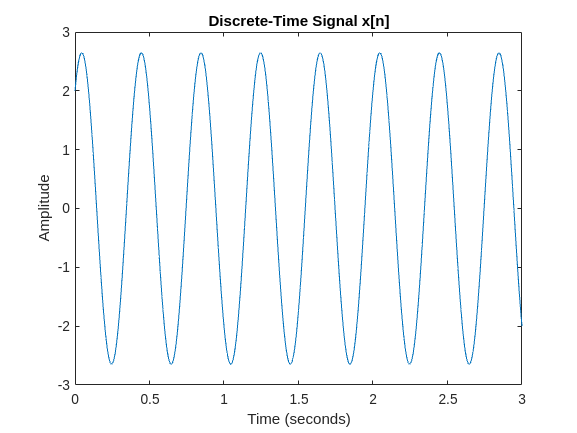

omega = linspace(-3*pi, 3*pi, 1000);
N = 5;
X_omega = sin(omega .* (N - 0.5)) ./ sin(omega / 2);

figure;
plot(omega, X_omega);
title('Magnitude of X(\omega) for N = 5');
xlabel('\omega (radians)');
ylabel('X(\omega)');

% Setting x-ticks to multiples of pi
xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi]);
xticklabels({'-3\pi', '-2\pi', '-\pi', '0', '\pi', '2\pi', '3\pi'});

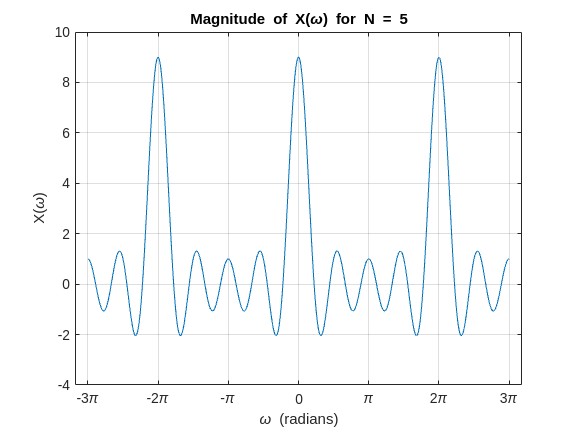

grid on;

### **Part 4: Discrete-Time Fourier Transform (DTFT) of signal y**

**Computing **$Y(\omega)$**, the DTFT of signal **$y$:


$$y[n] = \begin{cases} 
1 & \text{for } n \in [0, 2N-2] \\
0 & \text{for } n \notin 0, 2N-2]
\end{cases}
$$


*Using the shifting property of the DTFT the solution from part 2 can be modified by multiplying by an exponential with the shift amount in its expoent. The rectangular window function is now between *$[0, 8]$* whereas the previous one was between *$[-4,4]$. It was therefore shifted by $-N+1$. 


$$Y(\omega)  = e^{-j\omega (-N+1)}  \left( \frac{\sin\left(\omega\left(N - \frac{1}{2}\right)\right)}{\sin\left(\frac{\omega}{2}\right)} \right) = e^{j\omega (N-1)} \left( \frac{\sin\left(\omega\left(N - \frac{1}{2}\right)\right)}{\sin\left(\frac{\omega}{2}\right)} \right) 
$$


**Sources used to complete this section:**

- [https://www.youtube.com/watch?v=GKKv9T-noO0&ab_channel=MichelvanBiezen](https://www.youtube.com/watch?v=GKKv9T-noO0&ab_channel=MichelvanBiezen)

- [https://home.engineering.iastate.edu/~julied/classes/ee524/LectureNotes/l5.pdf](https://home.engineering.iastate.edu/~julied/classes/ee524/LectureNotes/l5.pdf)

- [https://www.site.uottawa.ca/~jpyao/courses/ELG3120_files/ELG3125-Formula-Sheets.pdf](https://www.site.uottawa.ca/~jpyao/courses/ELG3120_files/ELG3125-Formula-Sheets.pdf)

- https://www.mathworks.com/help/matlab/creating_plots/change-tick-marks-and-tick-labels-of-graph-1.html

## Exercise 4

**Computing the Inverse Discrete-Time Fourier Transform of a signal **$z$**, the expression of which is **$Z(\omega)$**:**


$$Z(\omega) = \frac{A}{1 - e^{(\alpha+j(\omega-\omega_0))}} + B e^{-j\omega n_0} \quad \text{with} \quad \alpha < 0
$$



$$z[n] = \mathcal{F}^{-1}(Z(\omega)) = \mathcal{F}^{-1}\left\{\frac{A}{1-e^{(\alpha+j(\omega-\omega_0))}}+Be^{-j{\omega}n_0}\right\}$$


*Linearity Property*


$$z[n] = \mathcal{F}^{-1}\left\{\frac{A}{1-e^{\left(\alpha+j\left(\omega-\omega_0\right)\right)}}\right\}+\mathcal{F}^{-1}\left\{Be^{-j{\omega}n_0}\right\}$$



$$z[n] = \left(A\right)\mathcal{F}^{-1}\left\{\frac{1}{1-e^{\left(\alpha+j\left(\omega-\omega_0\right)\right)}}\right\}+(B)\mathcal{F}^{-1}\left\{e^{-j{\omega}n_0}\right\}$$


*Shifting Property*


$$z[n] = \left(A\right)\mathcal{F}^{-1}\left\{\frac{1}{1-e^{\left(\alpha+j\left(\omega-\omega_0\right)\right)}}\right\}+(B)\mathcal{F}^{-1}\left\{1\right\}\left[n-n_0\right]$$


*Delta Dirac Replacement*


$$z[n] = \left(A\right)\mathcal{F}^{-1}\left\{\frac{1}{1-e^{\left(\alpha+j\left(\omega-\omega_0\right)\right)}}\right\}+(B)\left\{{\delta}[n]\right\}\left[n-n_0\right]$$


*Applying Time Shift to the Delta Dirac*


$$z[n] = \left(A\right)\mathcal{F}^{-1}\left\{\frac{1}{1-e^{\left(\alpha+j\left(\omega-\omega_0\right)\right)}}\right\}+B{\delta}\left[n-n_0\right]$$


*Frequency Shifting Property*


$$z[n] = \left(Ae^{j{\omega_0}n}\right)\mathcal{F}^{-1}\left\{\frac{1}{1-e^{\left(\alpha+j\omega\right)}}\right\}+B{\delta}\left[n-n_0\right]$$



$$z[n] = \left(Ae^{j{\omega_0}n}\right)\mathcal{F}^{-1}\left\{\frac{1}{1-e^{\alpha}e^{j\omega}}\right\}+B{\delta}\left[n-n_0\right]$$


*Unit Function Replacement*


$$z[n] = Ae^{j{\omega_0}n}e^{{\alpha}n}u[n]+B{\delta}\left[n-n_0\right]$$



$$z[n] = Ae^{n\left(j{\omega_0}+{\alpha}\right)}u[n]+B{\delta}\left[n-n_0\right]$$


**Sources used to complete this section:**

- [https://www.site.uottawa.ca/~jpyunit functionao/courses/ELG3120_files/ELG3125-Formula-Sheets.pdf](https://www.site.uottawa.ca/~jpyao/courses/ELG3120_files/ELG3125-Formula-Sheets.pdf)

- [https://www.site.uottawa.ca/~jpyao/courses/ELG3120_files/ch5.pdf](https://www.site.uottawa.ca/~jpyao/courses/ELG3120_files/ch5.pdf)

- https://tex.stackexchange.com/questions/113855/laplace-and-fourier-transforms